clc, clear

s = rng;
r = normrnd(3,2,[1, 3000])

r =     2.7311    2.8881    5.5181    2.1050    2.0980    2.2225    2.4317   -0.8004    4.6101    3.0284    3.5336    2.9458    1.7166    3.2373    6.9045    3.8741    2.9686    5.9476    4.5461    2.5381    1.9333    1.6896    1.8828   -0.5200    2.1551    1.1322   10.6964   -0.0737    2.5569    1.5946    2.6957    3.5809    5.5459    5.9183    1.5046    3.2715    1.8934    1.3703    5.5617    5.7534    2.6848    3.0180    1.5411    3.9834    1.0010   -0.4126    5.1862    3.8631    3.1033    4.8001


r(2001:end) = []

r =     2.7311    2.8881    5.5181    2.1050    2.0980    2.2225    2.4317   -0.8004    4.6101    3.0284    3.5336    2.9458    1.7166    3.2373    6.9045    3.8741    2.9686    5.9476    4.5461    2.5381    1.9333    1.6896    1.8828   -0.5200    2.1551    1.1322   10.6964   -0.0737    2.5569    1.5946    2.6957    3.5809    5.5459    5.9183    1.5046    3.2715    1.8934    1.3703    5.5617    5.7534    2.6848    3.0180    1.5411    3.9834    1.0010   -0.4126    5.1862    3.8631    3.1033    4.8001


T = readtable("Reward/RewardSet.csv", "VariableNamingRule","preserve");
T(2001:end, :) = []

T = 2000×3 table
    SJF reward    FIFO reward    Rand reward
    __________    ___________    ___________

        68            50            -1409   
        68            50            -1275   
        68            50             -399   
        68            50             -397   
        68            50             -579   
        68            50             -578   
        68            50             -824   
        68            50             -562   
        68            50             -364   
        68            50            -1639   
        68            50             -884   
        68            50            -1957   
        68            50             -924   
        68            50            -2250   
        68            50             -980   
        68            50             -312   


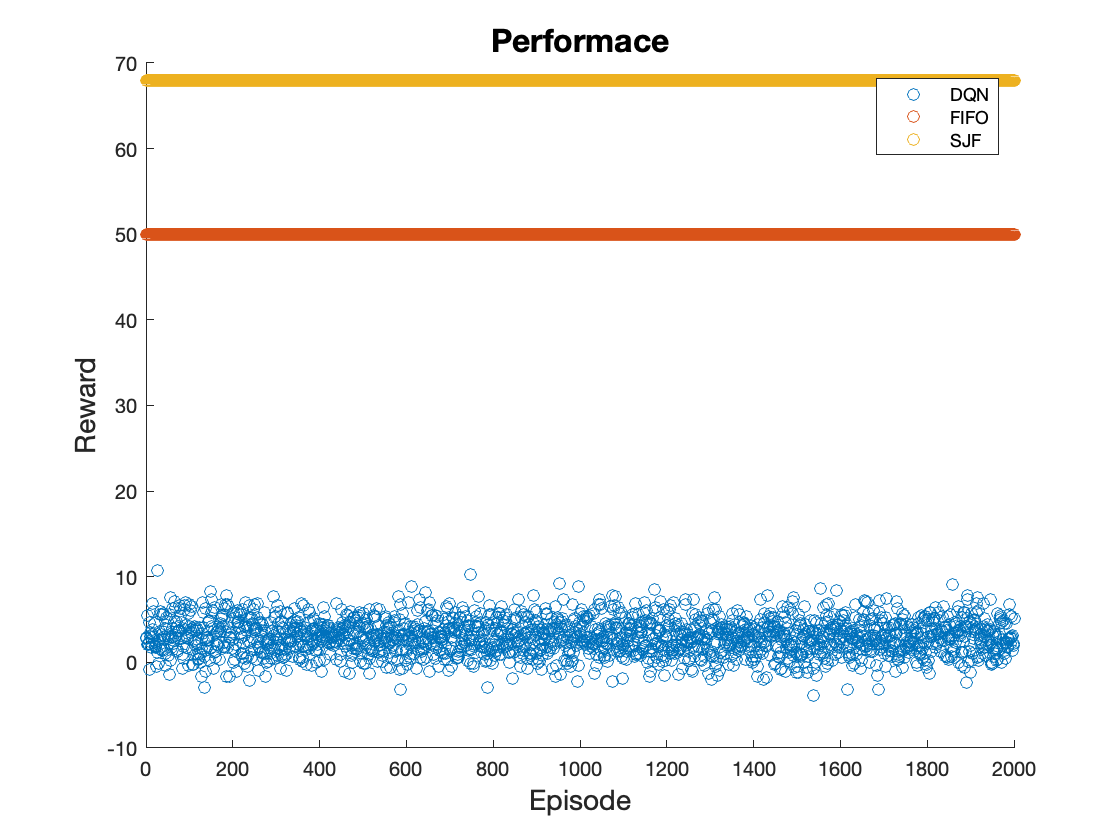

figure
scatter(1:2000, r)
hold on
scatter(1:2000, T.("FIFO reward"))
scatter(1:2000, T.("SJF reward"))
title('Performace', 'FontSize', 16)
xlabel('Episode', 'FontSize', 14)
ylabel('Reward', 'FontSize', 14)
legend('DQN', 'FIFO', 'SJF')